### Primera señal: Cuadrada

#### Dominio del tiempo

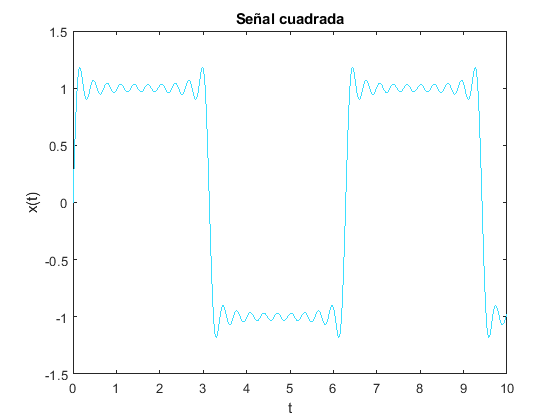

%Generemos la señal 

tArray = linspace(0,10, 10000);
xArray = zeros(length(tArray), 1);
nTerms = 10;


for i = 1:length(tArray)
    t = tArray(i);
    signalValue = 0;
    for j = 0:nTerms-1
        signalValue = signalValue + 4/((2*j + 1)*pi)*sin((2*j+1)*t);        
    end
    xArray(i) = signalValue; 
end


figure()
plot(tArray, xArray, "Color", '#3ddfff')
xlabel("t")
ylabel("x(t)")
title("Señal cuadrada")

### Espectro en dB

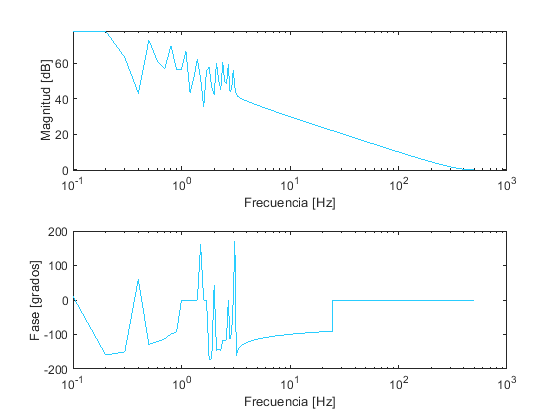

spectrumPlotter = SpectrumPlotter();
spectrumPlotter.spectrumWithLogarithmicScaleDB(tArray, xArray);

#### Espectro magnitud

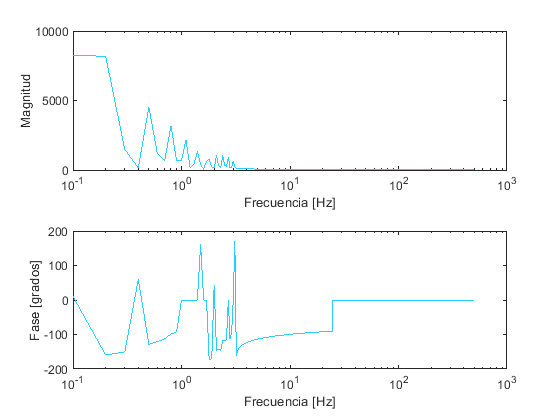


[fArr, magArr, phaseArr] = spectrumPlotter.spectrumWithLogarithmicScale(tArray, xArray);

#### Aplicación de media móvil 

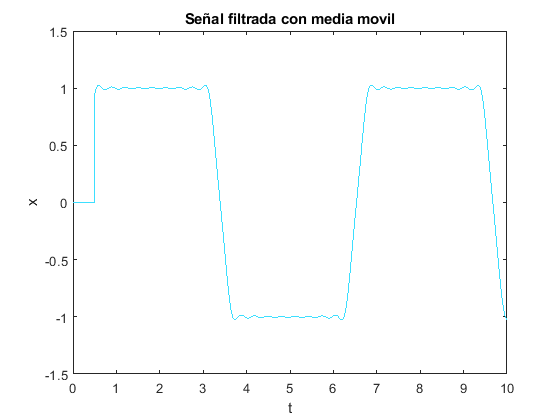

avgSize = 500;
bCoeffs = ones(avgSize, 1)*(1/avgSize);

filterer = Filterer();
xFiltered = filterer.applyFIRFilter(xArray, bCoeffs);

figure()
plot(tArray, xFiltered, "Color", "#3ddfff")
title("Señal filtrada con media movil")
xlabel("t")
ylabel("x")

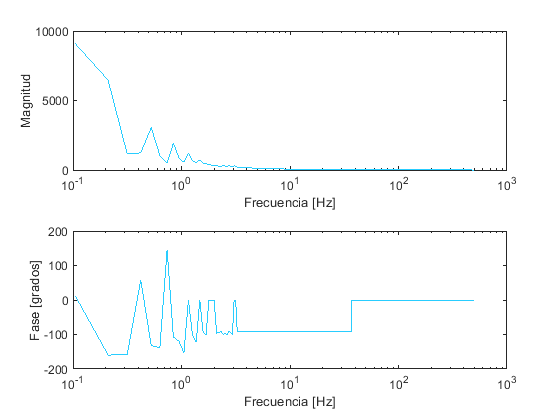

[fArrFiltered, magFiltered, phaseFiltered] = spectrumPlotter.spectrumWithLogarithmicScale(tArray(avgSize:end), xFiltered(avgSize:end));

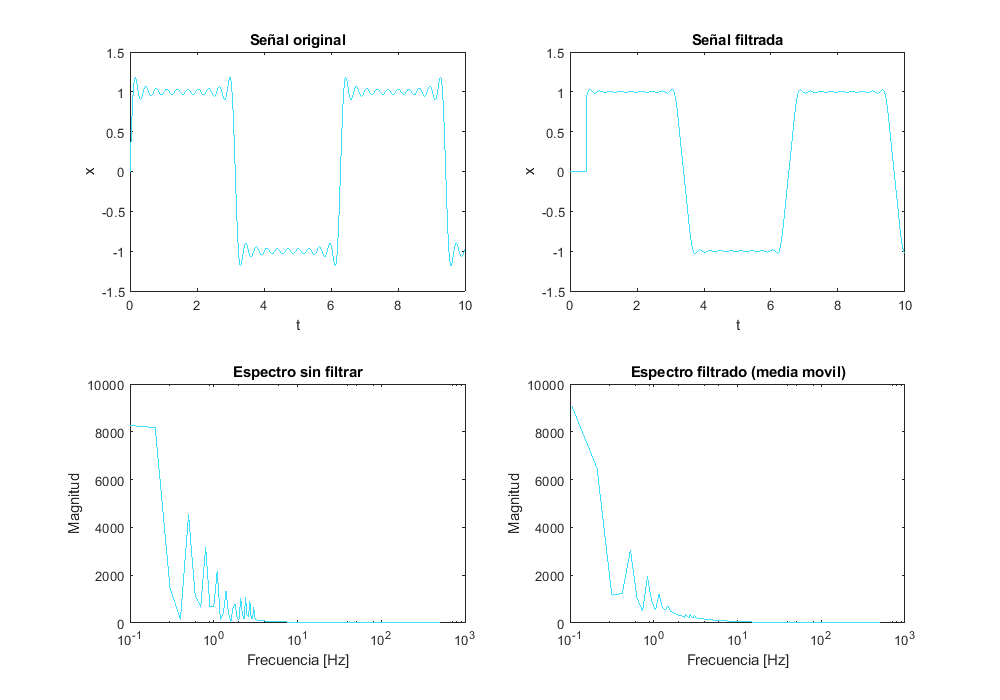

f = figure();
f.Position = [100 100 1000 700];
subplot(2,2,1)
plot(tArray, xArray, "Color", "#3ddfff")
xlabel("t")
ylabel("x")
title("Señal original")
subplot(2,2,2)
plot(tArray, xFiltered, "Color", "#3ddfff")
xlabel("t")
ylabel("x")
title("Señal filtrada")
subplot(2,2,3)
semilogx(fArr,magArr,"Color", "#3ddfff")
xlabel("Frecuencia [Hz]")
ylabel("Magnitud")
title("Espectro sin filtrar")
subplot(2,2,4)
semilogx(fArrFiltered, magFiltered, "Color", "#3ddfff")
xlabel("Frecuencia [Hz]")
ylabel("Magnitud")
title("Espectro filtrado (media movil)")

### Señal triangular

#### Señal

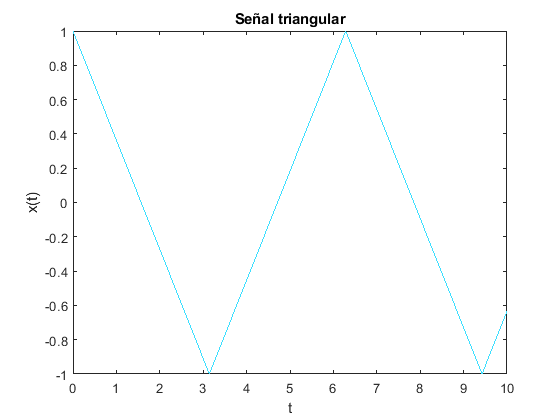

tArray = linspace(0,10, 10000);
xArray = zeros(length(tArray), 1);
nTerms = 100;


for i = 1:length(tArray)
    t = tArray(i);
    signalValue = 0;
    for j = 0:nTerms-1
        signalValue = signalValue + 8/((2*j + 1)^2*pi^2)*cos((2*j+1)*t);        
    end
    xArray(i) = signalValue; 
end


figure()
plot(tArray, xArray, "Color", '#3ddfff')
xlabel("t")
ylabel("x(t)")
title("Señal triangular")

#### Espectros

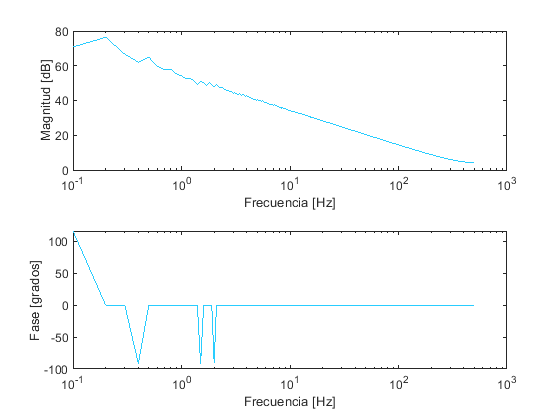

spectrumPlotter = SpectrumPlotter();
spectrumPlotter.spectrumWithLogarithmicScaleDB(tArray, xArray);

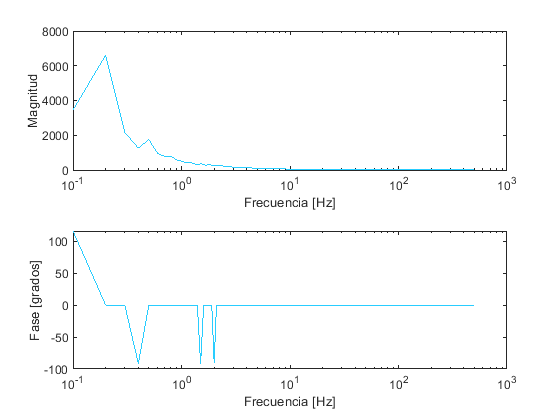

[fArr, magArr, phaseArr] = spectrumPlotter.spectrumWithLogarithmicScale(tArray, xArray);

#### Aplicación de media móvil

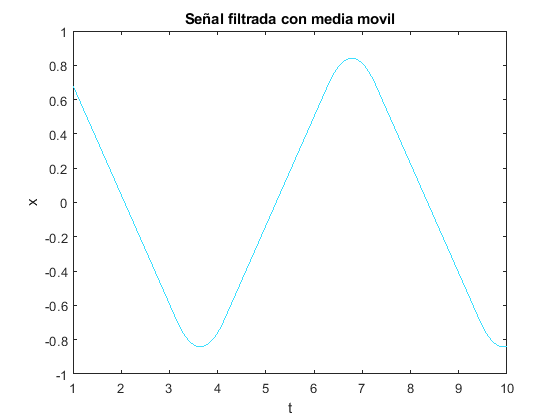

avgSize = 1000;
bCoeffs = ones(avgSize, 1)*(1/avgSize);

filterer = Filterer();
xFiltered = filterer.applyFIRFilter(xArray, bCoeffs);

figure()
plot(tArray(avgSize+1:end), xFiltered(avgSize+1:end), "Color", "#3ddfff")
title("Señal filtrada con media movil")
xlabel("t")
ylabel("x")

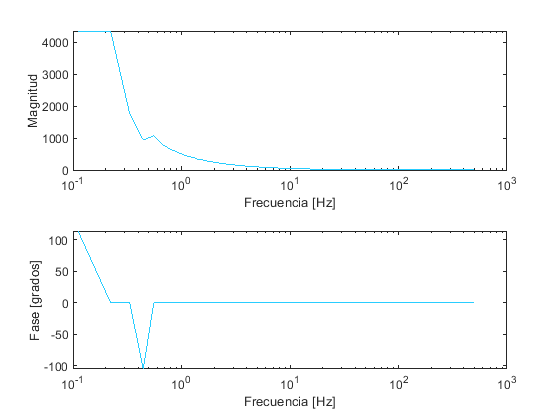

[fArrFiltered, magFiltered, phaseFiltered] = spectrumPlotter.spectrumWithLogarithmicScale(tArray(avgSize:end), xFiltered(avgSize:end));

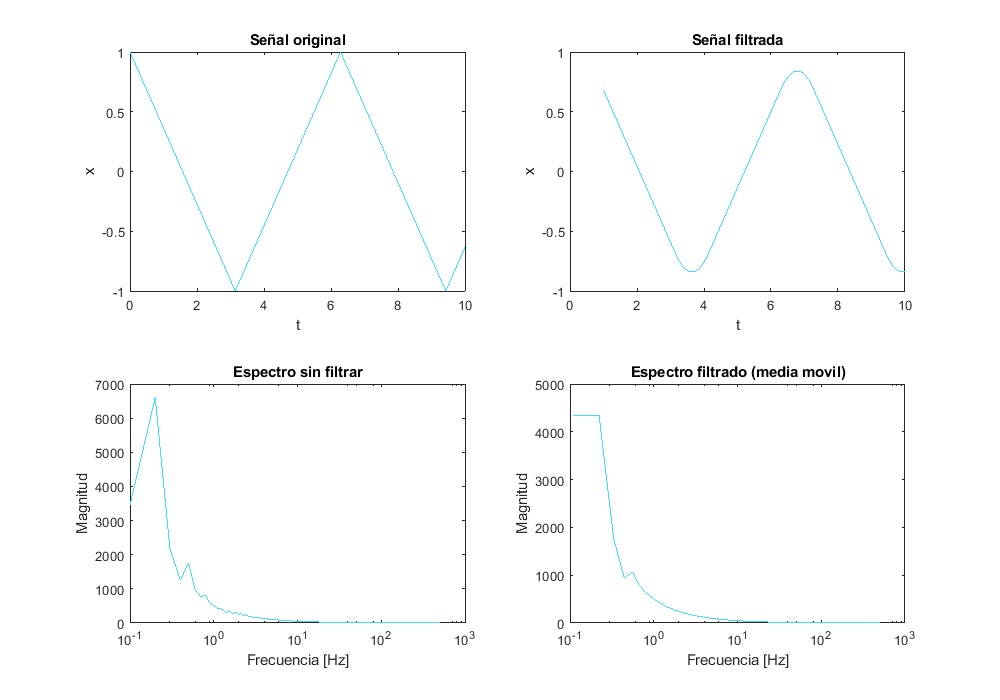

f = figure();
f.Position = [100 100 1000 700];
subplot(2,2,1)
plot(tArray, xArray, "Color", "#3ddfff")
xlabel("t")
ylabel("x")
title("Señal original")
subplot(2,2,2)
plot(tArray(avgSize+1:end), xFiltered(avgSize+1:end), "Color", "#3ddfff")
xlabel("t")
ylabel("x")
title("Señal filtrada")
subplot(2,2,3)
semilogx(fArr,magArr,"Color", "#3ddfff")
xlabel("Frecuencia [Hz]")
ylabel("Magnitud")
title("Espectro sin filtrar")
subplot(2,2,4)
semilogx(fArrFiltered, magFiltered, "Color", "#3ddfff")
xlabel("Frecuencia [Hz]")
ylabel("Magnitud")
title("Espectro filtrado (media movil)")